clc; clear; close all

I personally recommend starting scripts with a clearing of the command window, the workspace and all figures. Not for performance, but so that you always get a clean slate at the start when you are running your programs and make sure that they will work as intended in the future. Otherwise, sometimes there are old definitions of variables or settings that get in the way as you re-write your program the first time!

# **Manipulating arrays**

## **Array indexing**

% For vectors (1D arrays)
u = [1, 2, 1]

u =      1     2     1


v = [1; -2; 1]

v =      1
    -2
     1


v(1)
v(2)
v(end)      % the end keyword allows you to access the last element of the vector
v(end-1)    % you can even use it to "count backwards"

% For matrices (2D arrays)
A = [1, 2, 3; 4, 5, 6; 7, 8, 9]

A(2,1)
A(1)
% colon operator is shorthand for "everything in this dimension"
A(:,1)
A(2,:)
A(:)       

## Array concatenation

a = [1, 2, 3]
[a;a;a]
b = [[1, 2]; [3, 4]]
AA = [A(:,1) A(:,end)]

It is also possible to append items to an array by assigning it to "non-existent" entries. In this example, the vector "x" only has one component, but we can still assign an element to x(2) and MATLAB will automatically extend the vector to accomodate this. *Note that, for performance reasons, MATLAB recommends pre-allocating the vectors instead of dynamically extending their size.*

%x = zeros(6,1);
x = 0

x = 0

for i = 1:4
    y(i) = 2*x(i)
    x(i+1) = y(i) + 1
end

y =      0     2     6    14


x =      0     1


y =      0     2     6    14


x =      0     1     3


y =      0     2     6    14


x =      0     1     3     7


y =      0     2     6    14


x =      0     1     3     7    15


i = 0;
while i < 5
    fprintf("Number is %i\n",i)
    i = i + 1;
end

Number is 0
Number is 1
Number is 2
Number is 3
Number is 4



z = 1;
for i = 1:3
    z(end+1) = z(end) + 1
end

z =      1     2


z =      1     2     3


z =      1     2     3     4


## Slightly more advanced indexing

rv = rand(10,1) 
ind = 1:3
odd_less_than_10 = 1:2:10
rv(ind)
rv(odd_less_than_10)

% In this case, rv > 0.5 is an array itself. A logic array of 0s and 1s that 
% we use to extract values (where the 1s are positioned) from rv
rv(rv > 0.5) 

## **Operating with arrays**

% Vector-vector operations
v1 = [1; 2; 3]

v1 =      1
     2
     3


v2 = [10; 100; 10]

v2 =     10
   100
    10


% Vector sum
v1 + v2

ans =     11
   102
    13


% Linear combination
3*v1 - 6*v2

ans =    -57
  -594
   -51


% Inner product
v1'*v2

ans = 240

% Element-wise product
v1.*v2

ans =     10
   200
    30


% 2-norm
norm(v1)

ans = 3.7417

sqrt(sum(v1.^2))

ans = 3.7417

M = [1, 1, 1; 2, 2, 2; 3, 3, 3]
% Matrix-vector multiplication
v3 = [1; 2; 0];
M*v3
% Some special operations
M + v3
M + v3'
M.*v3
M.*v3'

% Matrix-matrix operations
A*M
M*A
M*M
M.^2

% Other special operations
v4 = [10; 100; 1000]
1./v4
2.^(1:5)

# **Useful functions**

v = [10; -5; -10];

% 2-norm of a vector/matrix
norm(v)

ans =     15


% sum of elements
sum(v)

ans =     -5


% absolute value (applied element-wise)
abs(v)

ans =     10
     5
    10


% logarithm (applied element-wise)
log(abs(v))

ans =    2.3026e+00
   1.6094e+00
   2.3026e+00


% size of an array
size(v)

ans =      3     1


% evenly spaced points between two values
linspace(0,1,10)

ans =             0   1.1111e-01   2.2222e-01   3.3333e-01   4.4444e-01   5.5556e-01   6.6667e-01   7.7778e-01   8.8889e-01   1.0000e+00


% array of 1s
ones(5,1)

ans =      1
     1
     1
     1
     1


% array of 0s
zeros(1,3)

ans =      0     0     0


% identity matrix
eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


% constructing a sparse (more efficiently stored) matrix
S = sparse([1 2, 1 2 3, 2 3],[1 1, 2, 2, 2, 3, 3],[2 -1, -1 2 -1, -1 2])

S =    (1,1)        2
   (2,1)       -1
   (1,2)       -1
   (2,2)        2
   (3,2)       -1
   (2,3)       -1
   (3,3)        2


% obtain the full version of a sparse matrix
fS = full(S)

fS =      2    -1     0
    -1     2    -1
     0    -1     2


% compute eigenvectors and eigenvalues
[V, D] = eig(fS)

V =    5.0000e-01  -7.0711e-01  -5.0000e-01
   7.0711e-01   4.8851e-17   7.0711e-01
   5.0000e-01   7.0711e-01  -5.0000e-01


D =    5.8579e-01            0            0
            0   2.0000e+00            0
            0            0   3.4142e+00


fS*V(:,1) - D(1)*V(:,1) % fS*v = lambda_v * v

ans =   -1.1102e-16
  -2.7756e-16
  -1.6653e-16


fS - V*D*V'

ans =    1.1102e-15  -9.9920e-16   1.1102e-16
  -9.9920e-16   1.3323e-15  -1.3323e-15
   1.1102e-16  -1.3323e-15   1.5543e-15


Note that, given the default arithmetic precision, we can consider values between 10^-15 and 10^-16 to be "practically" zero.

# **Plotting**

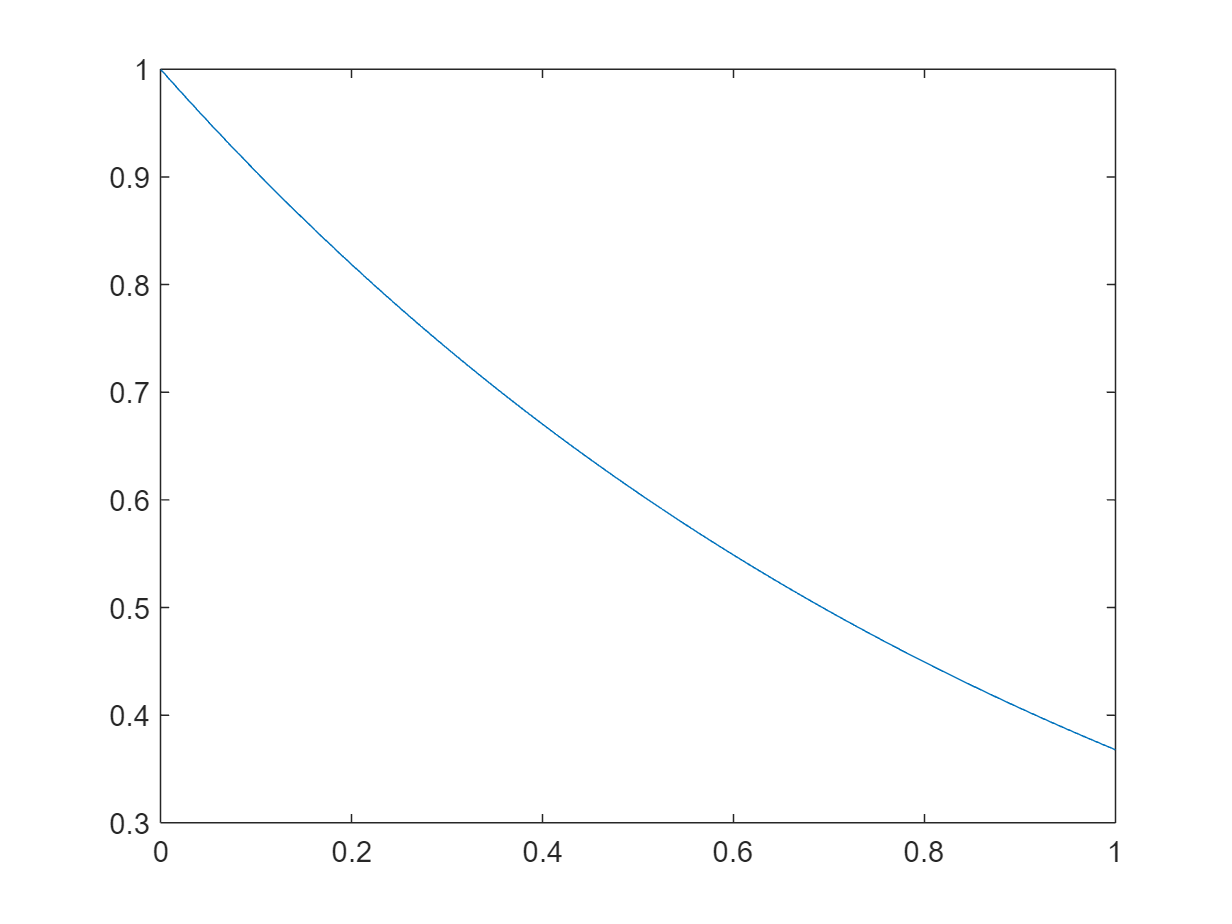

tt = linspace(0,1);
f = @(t) exp(-t);
g = @(t) 1./(exp(t) + 1);

% Simple plot
plot(tt,f(tt))

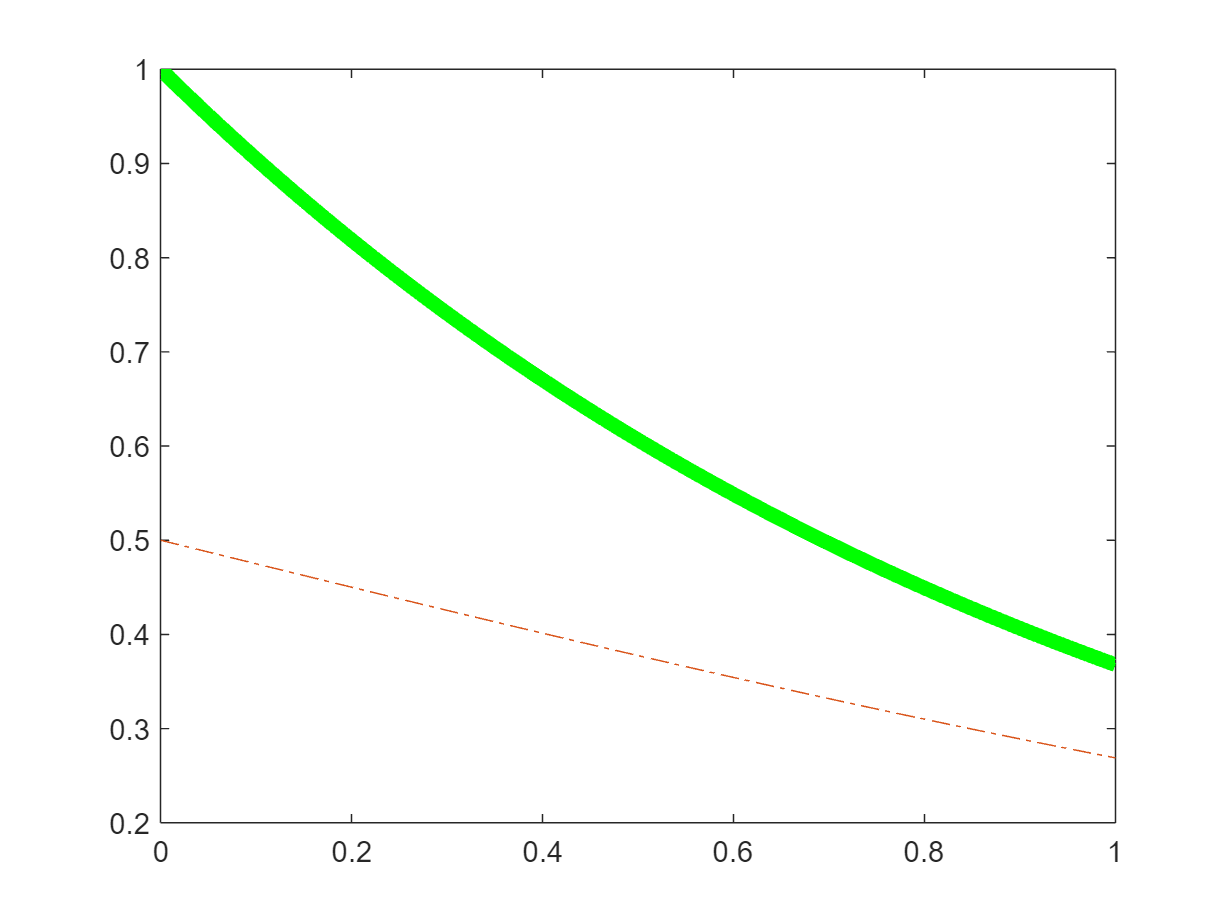

% Adding more plots to a single figure
plot(tt,f(tt),'Color','g','LineWidth',5);
hold on
plot(tt,g(tt),'LineStyle','-.')
hold off

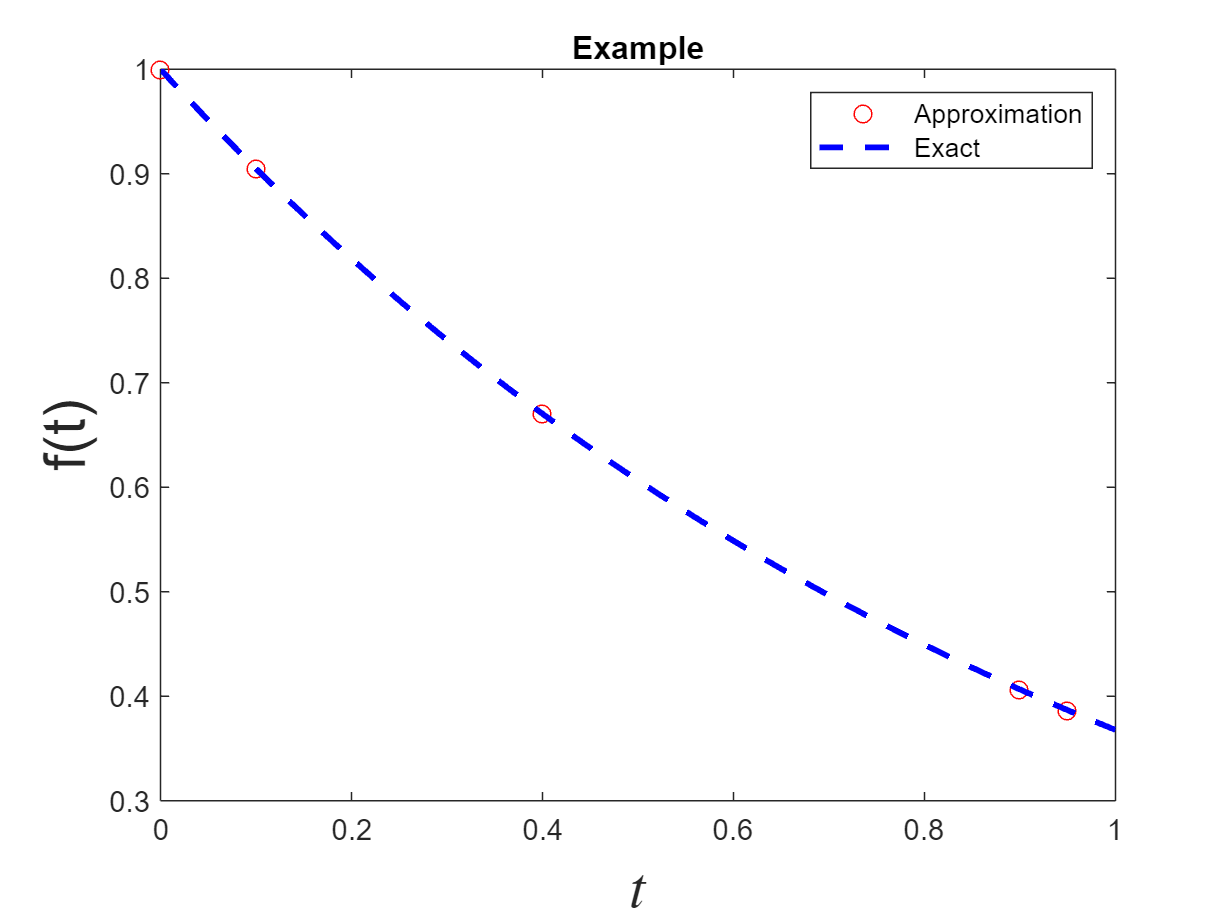

% Making plots nicer
sample = [0 0.1 0.4 0.9 0.95];
plot(sample,f(sample),'ro',...
    'DisplayName', "Approximation")
hold on
plot(tt,f(tt),'b--',...
    'LineWidth', 2, ...
    "DisplayName", "Exact")
hold off
legend show
xL = xlabel("$t$",'Interpreter','latex');
yL = ylabel("f(t)");
set([xL, yL], 'FontSize', 20);
title("Example")
exportgraphics(gcf,"ExampleFigure.png",'resolution',300)